# Práctica 5 - Prefijo cíclico

## 2.1. Convolución Circular 

**1. Obtenga una señal aleatoria x[n], especificando su longitud N (en cualquier caso mayor o igual que 64) y el periodo de muestreo Ts. Obtenga y represente gráficamente su espectro, X[k], indicando en el eje de frecuencias las frecuencias positivas y negativas, así como la escala de frecuencias.**

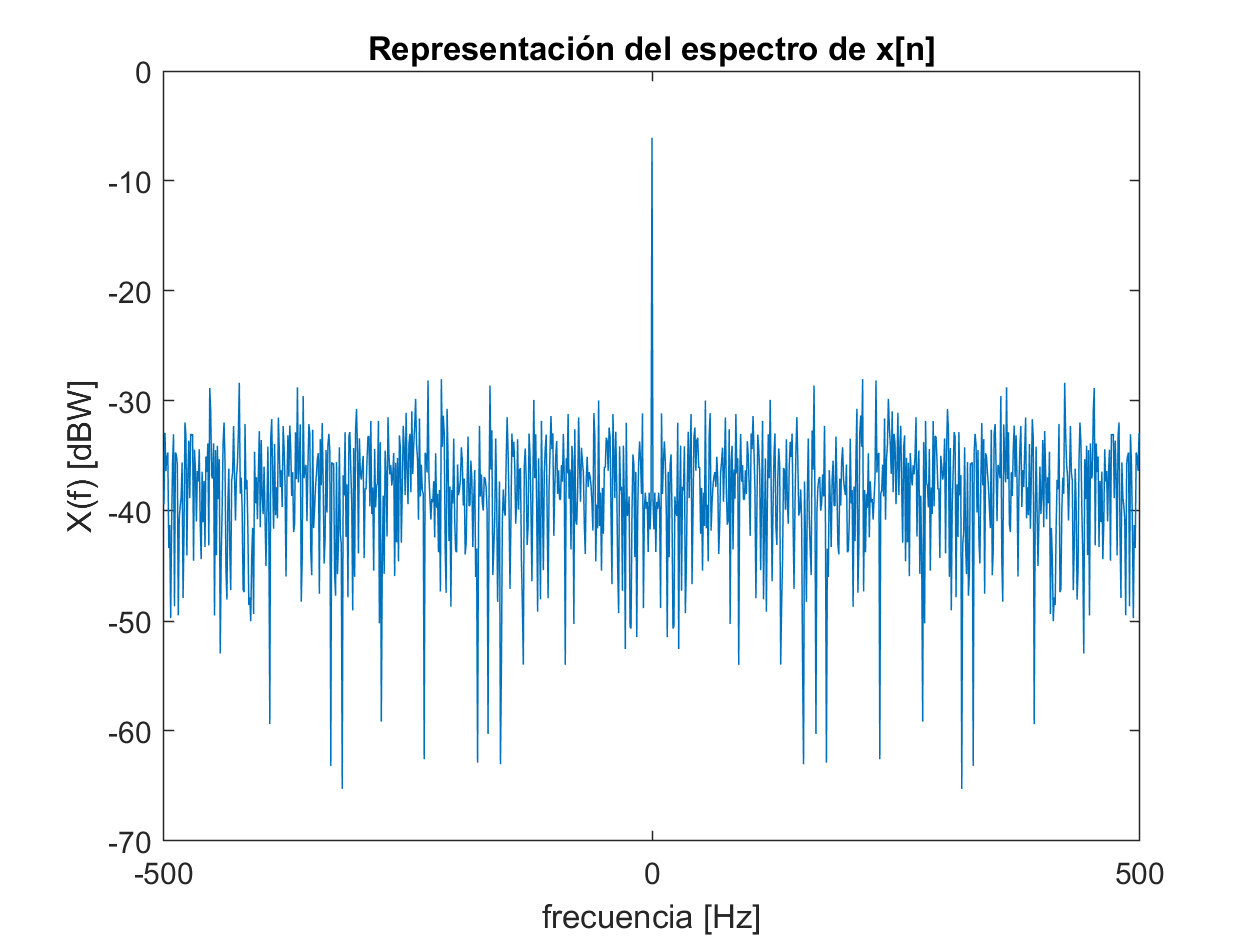

% Parametros
N = 1024; % Longitud
Ts = 0.001; % 1 ms
Fs = 1/Ts;
x_n = randi([0 1],1,N); % señal aleatoria x[n]

% Espectro de x[n]
X_f = fft(x_n,N)/N;
f = -1/(2*Ts):1/(N*Ts):1/(2*Ts)-1/(N*Ts);
X_f_dBW = 20*log10(abs(X_f)); 

% Representacion del espectro x[n]
figure;
plot(f,fftshift(X_f_dBW));
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("X(f) [dBW]");
title("Representación del espectro de x[n]");

**2. Definición de la respuesta impulsiva del canal h[n]. Calcule y represente su espectro, H, de forma análoga a la de X.**

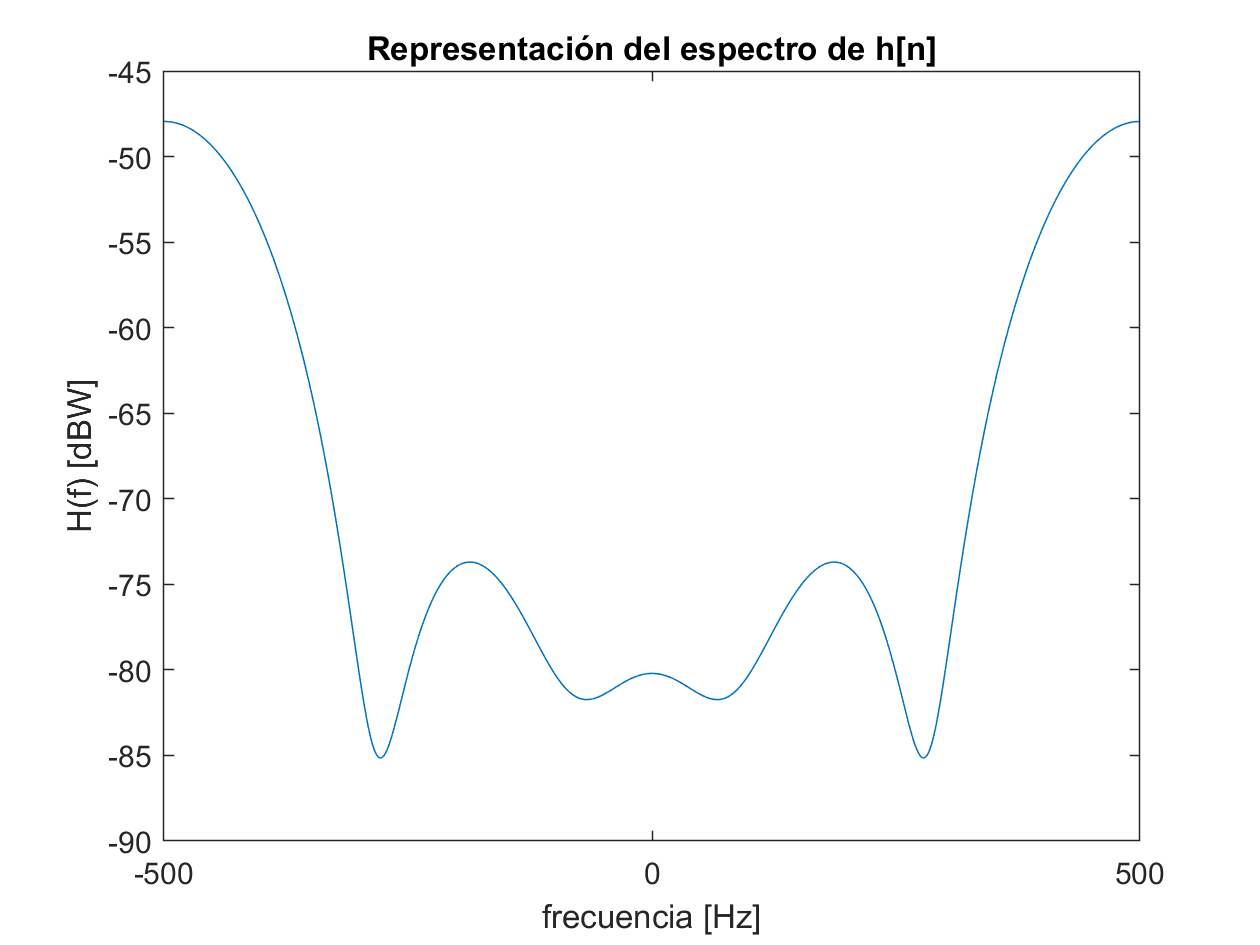

% Definicion del canal
h_n = [-0.1	0.3	-0.5 0.7 -0.9 0.7 -0.5 0.3 -0.1];

% Espectro de h[n]
H_f = fft(h_n,N)/N;
H_f_dBW = 20*log10(abs(H_f)); 

% Representacion del espectro h[n]
figure;
plot(f,fftshift(H_f_dBW));
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("H(f) [dBW]");
title("Representación del espectro de h[n]");

**3. Calcule la convolución lineal entre ambas, y = lconv(x,h), y su transformada de Fourier Y. Represente gráficamente Y de forma análoga a como lo ha hecho con X y H.**

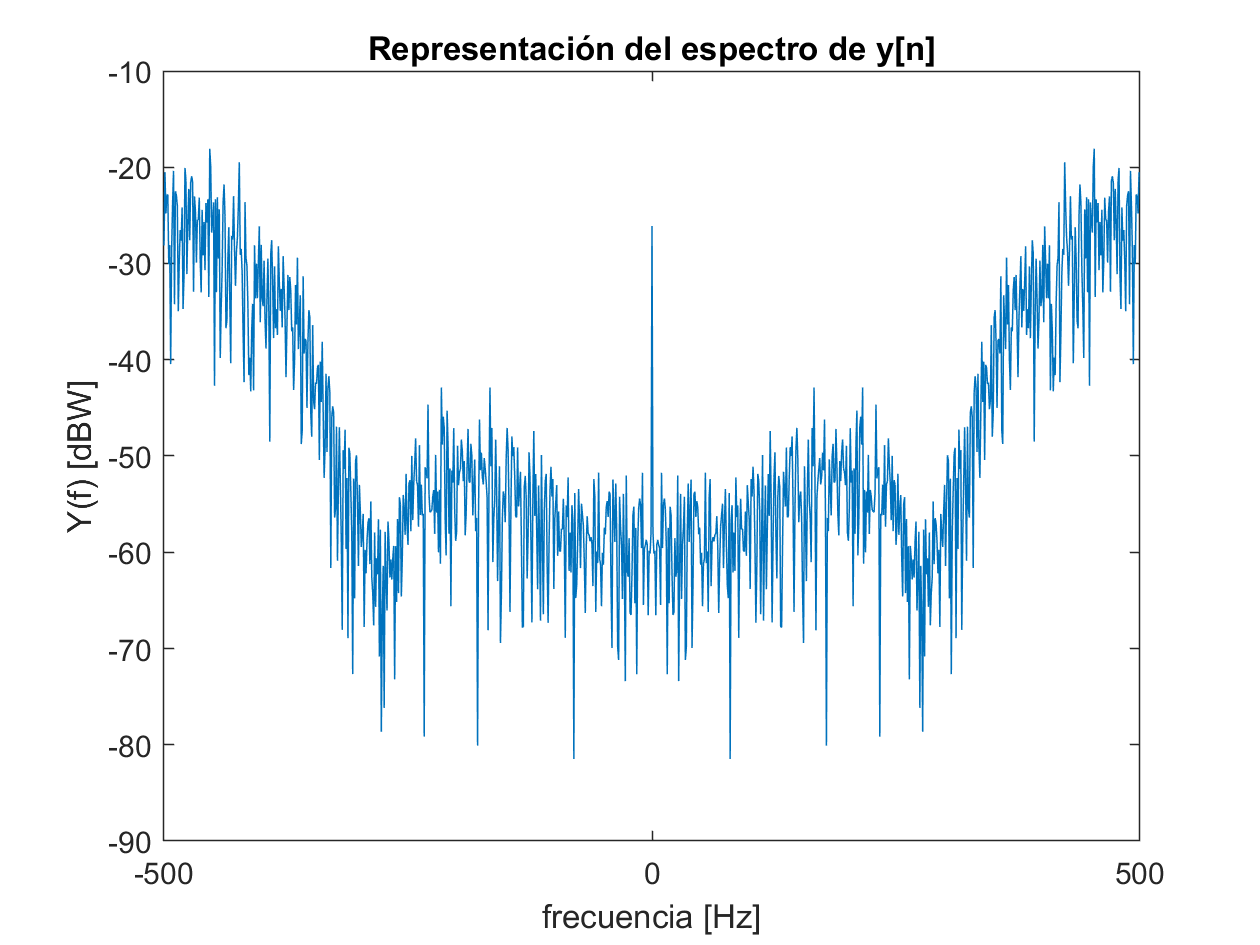

% Convolucion lineal entre x[n] y h[n]
y_n = conv(x_n,h_n);

% Espectro de y[n]
Y_f = fft(y_n,N)/N;
Y_f_dBW = 20*log10(abs(Y_f)); 

% Representacion del espectro y[n]
figure;
plot(f,fftshift(Y_f_dBW));
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("Y(f) [dBW]");
title("Representación del espectro de y[n]");

**4. Calcule la convolución circular yc = cconv(x,h). Puede utilizar la función cconv de Matlab, entendiendo cómo debe emplearse. Indíquese cómo se ha empleado. Calcule y represente su espectro Yc.**

% Convolucion circular 
yc_n = cconv(x_n,h_n,N);

Para relizar la convolución circular de la señal x[n] con el filtro h[n] se ha debido de especificar el número de puntos, en este caso es N, es decir, la longitud de la señal de entrada x[n]. 

Se comprueba cómo la salida yc[n] posee N muestras, tal y cómo se ha indicado en la llamada de la función. 

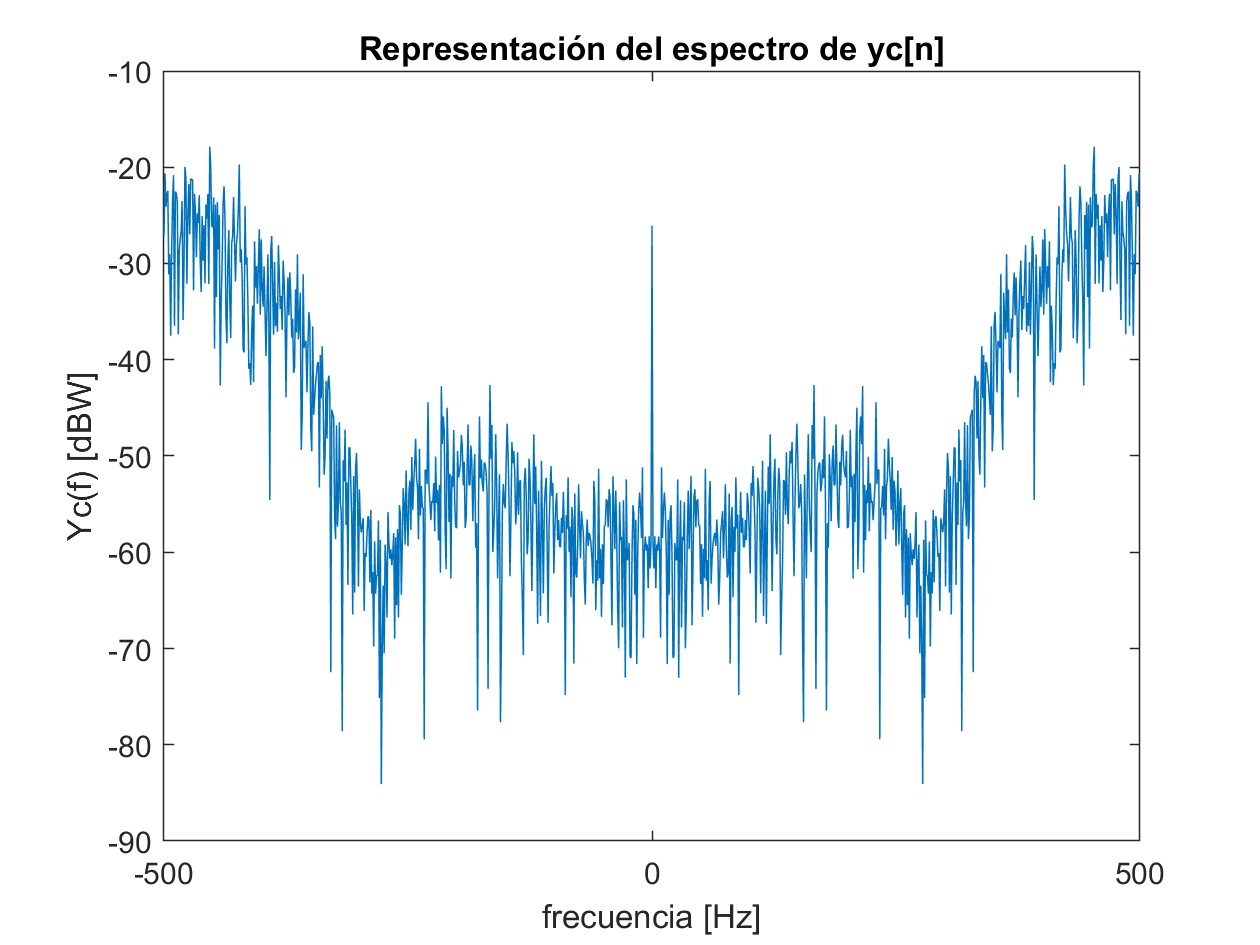

% Espectro de yc[n]
Yc_f = fft(yc_n,N)/N;
Yc_f_dBW = 20*log10(abs(Yc_f));

% Representacion del espectro yc[n]
figure;
plot(f,fftshift(Yc_f_dBW));
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("Yc(f) [dBW]");
title("Representación del espectro de yc[n]");

**5. Demuestre que X·H ≠ Y, y también que X·H = Yc**

Primero comprobamos que se cumple X·H ≠ Y:

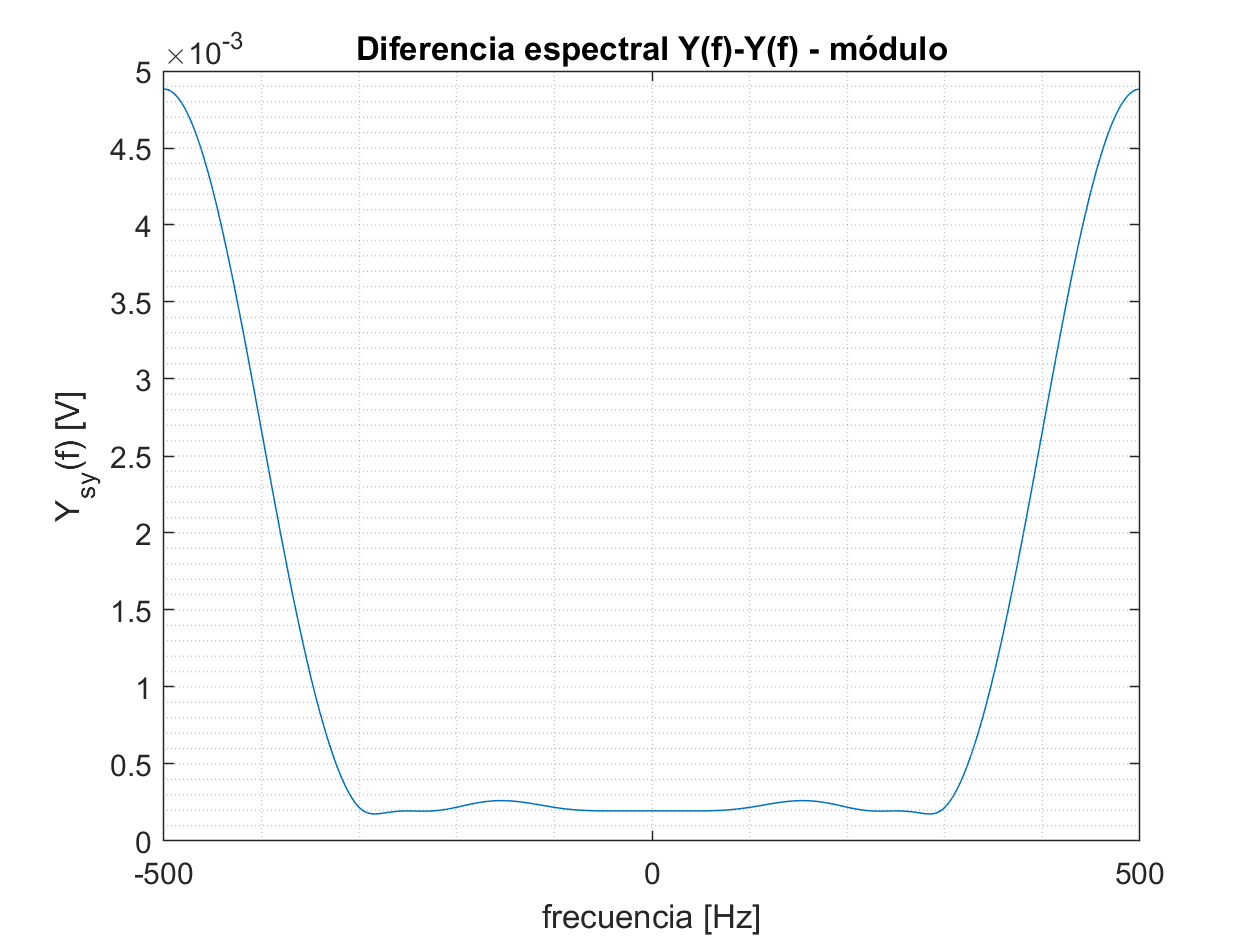

Ys_f = X_f.*H_f*N; % Operacion

% Comprobar si X·H ≠ Y
Y_s_y_f = Ys_f - Y_f;

% Espectro de la diferencia Ys-Y en módulo
figure;
plot(f,abs(fftshift(Y_s_y_f)));
grid minor;
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("Y_s_y(f) [V]");
title("Diferencia espectral Y(f)-Y(f) - módulo");

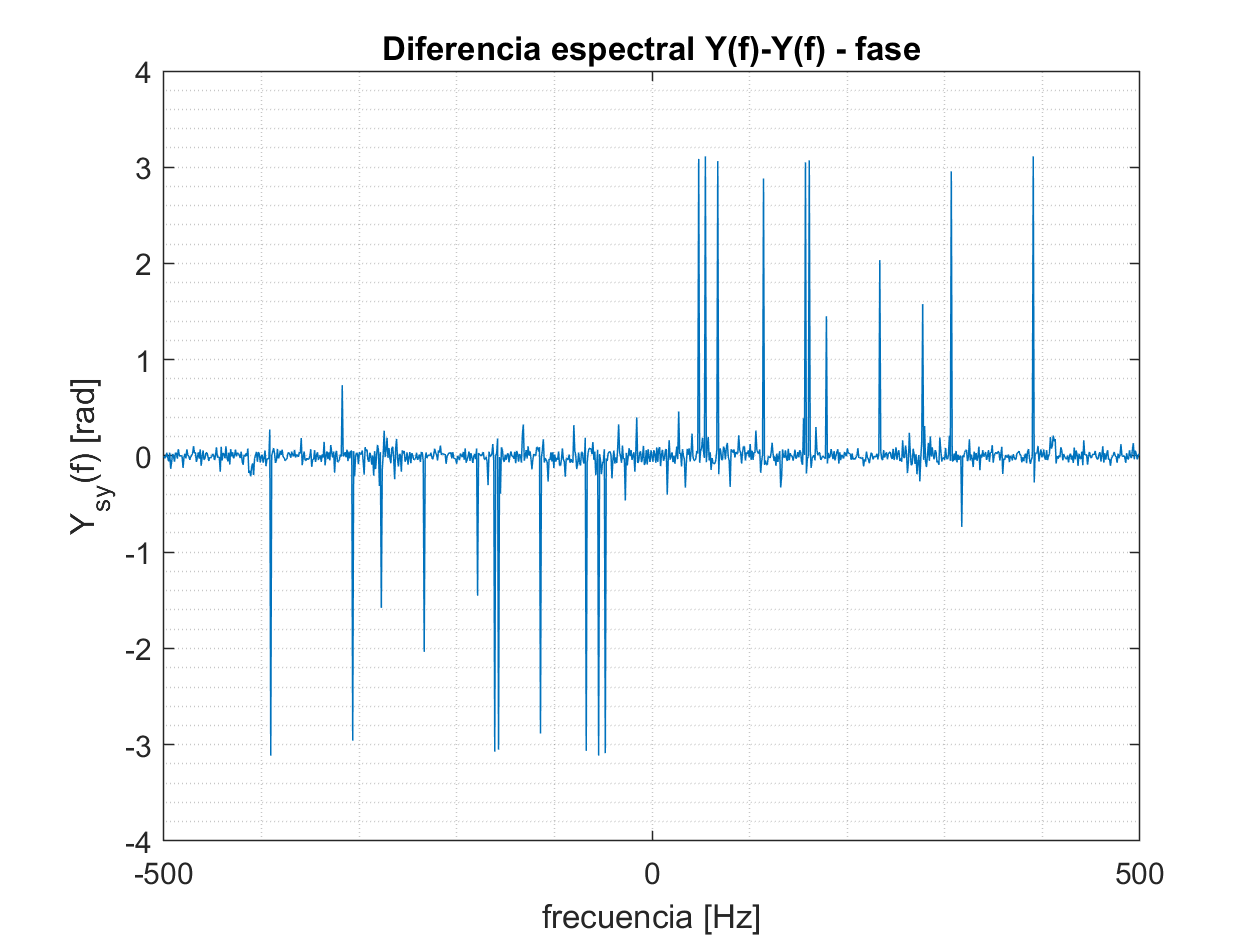


% Espectro de la diferencia Ys-Y en fase
figure;
plot(f,(angle(fftshift(Ys_f))-angle(fftshift(Y_f)))/2);
grid minor;
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("Y_s_y(f) [rad]");
title("Diferencia espectral Y(f)-Y(f) - fase");


% Error total de la diferencia Ys-Y
err_s_y = sum(abs(Y_s_y_f))

err_s_y = 1.2104


if err_s_y < 1e-3
    disp("Son equivalentes. X·H = Y.");
else
    disp("No son equivalentes. X·H ≠ Y.");
end

No son equivalentes. X·H ≠ Y.


Se puede apreciar como tanto en la representación de la diferencia de módulo y de fase existen discrepancias notables que permiten afirmar que la igualdad de X·H = Y no se cumple. En el caso del módulo, la diferencia alcanza los 2.3*10^-3 V, y en el caso de la fase, para determinadas muestras de la señal el desfase máximo (-pi y pi rad).  

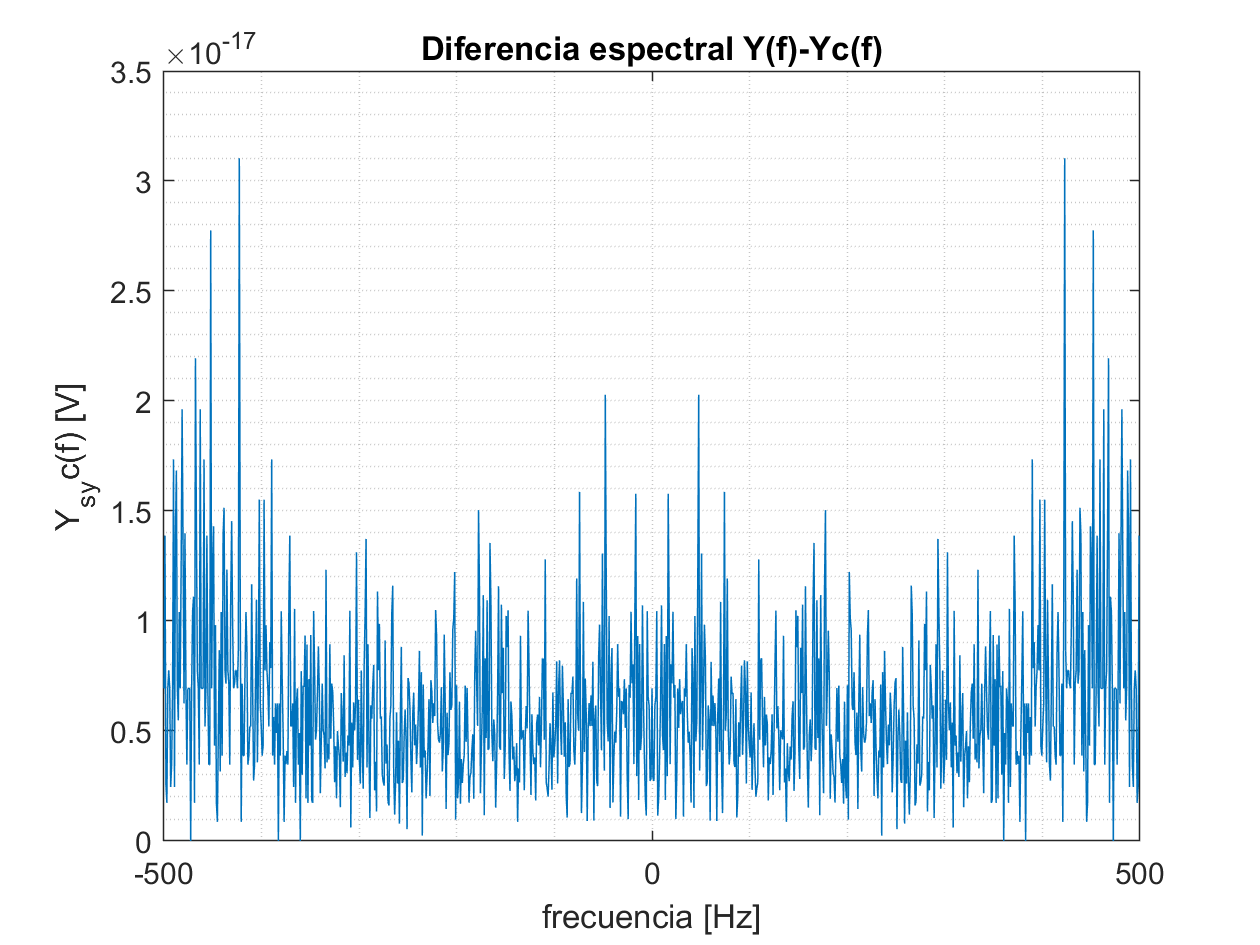

% Comprobar si X·H ≠ Yc
Y_s_yc_f = Ys_f - Yc_f;

% Espectro de la diferencia Ys-Yc en módulo
figure;
plot(f,abs(fftshift(Y_s_yc_f)));
grid minor;
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("Y_s_yc(f) [V]");
title("Diferencia espectral Y(f)-Yc(f)");

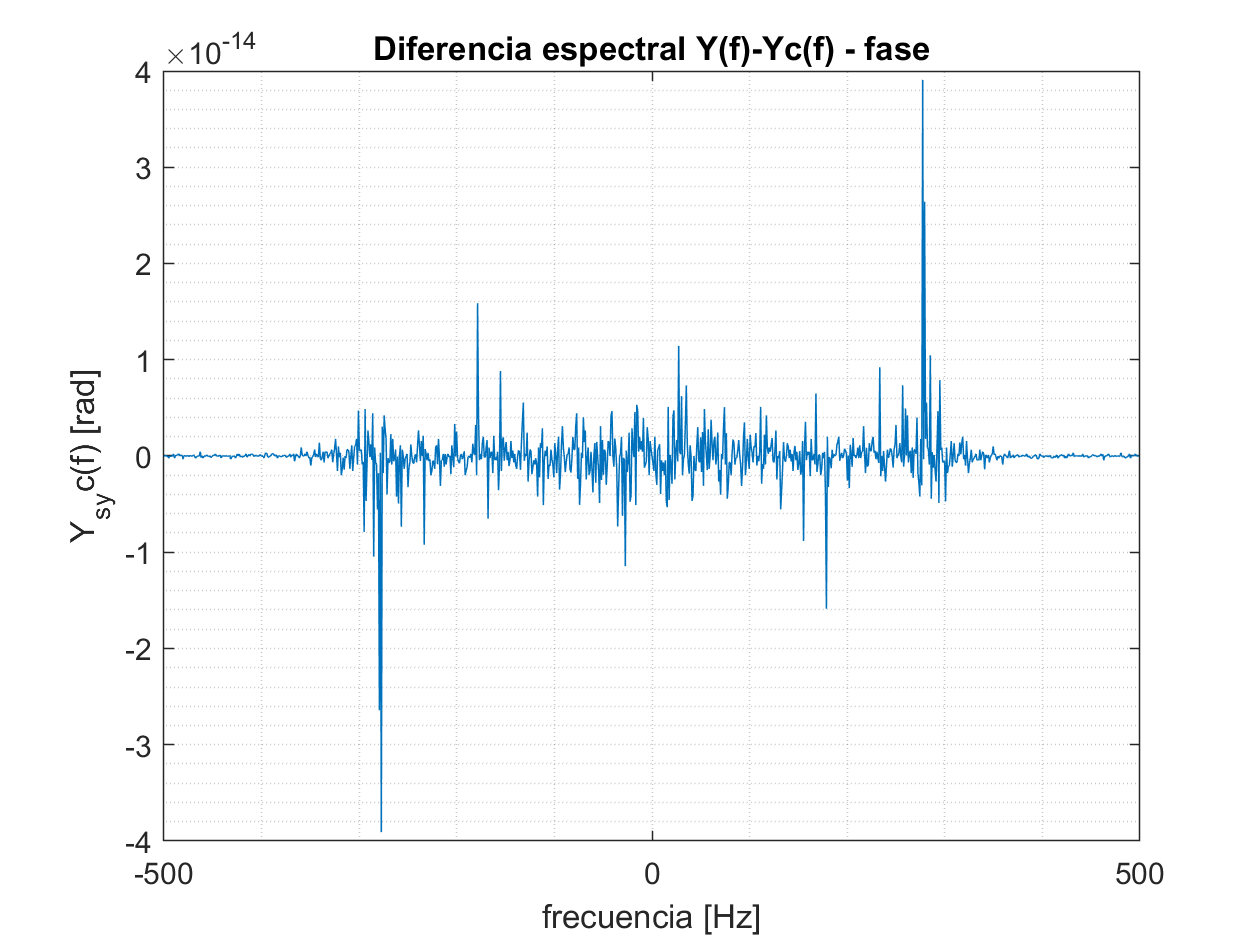


% Espectro de la diferencia Ys-Yc en fase
figure;
plot(f,(angle(fftshift(Ys_f))-angle(fftshift(Yc_f)))/2);
grid minor;
xlim([-Fs/2 Fs/2]);
xlabel("frecuencia [Hz]");
ylabel("Y_s_yc(f) [rad]");
title("Diferencia espectral Y(f)-Yc(f) - fase");


% Error total de la diferencia Ys-Yc
err_s_yc = sum(abs(Y_s_yc_f))

err_s_yc = 6.3323e-15


if err_s_yc < 1e-3
    disp("Son equivalentes. X·H = Yc.");
else
    disp("No son equivalentes. X·H ≠ Yc.");
end

Son equivalentes. X·H = Yc.


En el caso de X·H ≠ Yc, se comprueba que la diferencia es de una magnitud muy pequeña (2.3*10^-17 V), lo que afectos prácticos es prácticamente nulo. Asimismo, la diferencia de fase también varía en magnitudes muy pequeñas, de apenas 1.5*10^-14 rad, que puede ser considerada como cero. De este modo, se puede afirmar que se cumple la igualdad. 

**6. Construya la señal extendida con prefijo cíclico xext. Explique razonadamente la longitud elegida de prefijo cíclico. ¿Cuál sería la longitud óptima para el canal definido en el punto 2 (razónelo de forma cuantitativa)?**

% Añadir prefijo cíclico
K = length(h_n) - 1;
xext_n = [x_n(end-K+1:end) x_n];

La longitud óptima de muestras que se deben añadir tiene que ser igual a la longitud del filtro menos uno. En caso de utilizar más muestras, la señal de salida se vería retardada en un inicio en tantas muestras como valores adicionales se hayan añadido con respecto a esta longitud óptima. En caso de añadir menos muestras, aparece distorsión en la salida. 

A nivel cuantitativo, como la longitud del filtro h[n] es de K = 9 muestras, la longitud óptimo del prefijo cíclico debe ser de K -1 = 8 muestras.

**7. Calcule yext = lconv(xext,h), y extraiga yc de yext. Indique con texto y de alguna manera gráfica cómo obtiene yc de yext.**

% Convolucion extendida 
yext_n = conv(xext_n,h_n);

% Extracción de yc
yc_ext_n = yext_n(K+1:end);

La señal yc extendida es el resultado de eliminar las K primeras muestras de la señal yc obtenida de la convolución circular. El motivo es que estas muestras coinciden con las muestras del prefijo cíclico que han sido procesadas. 

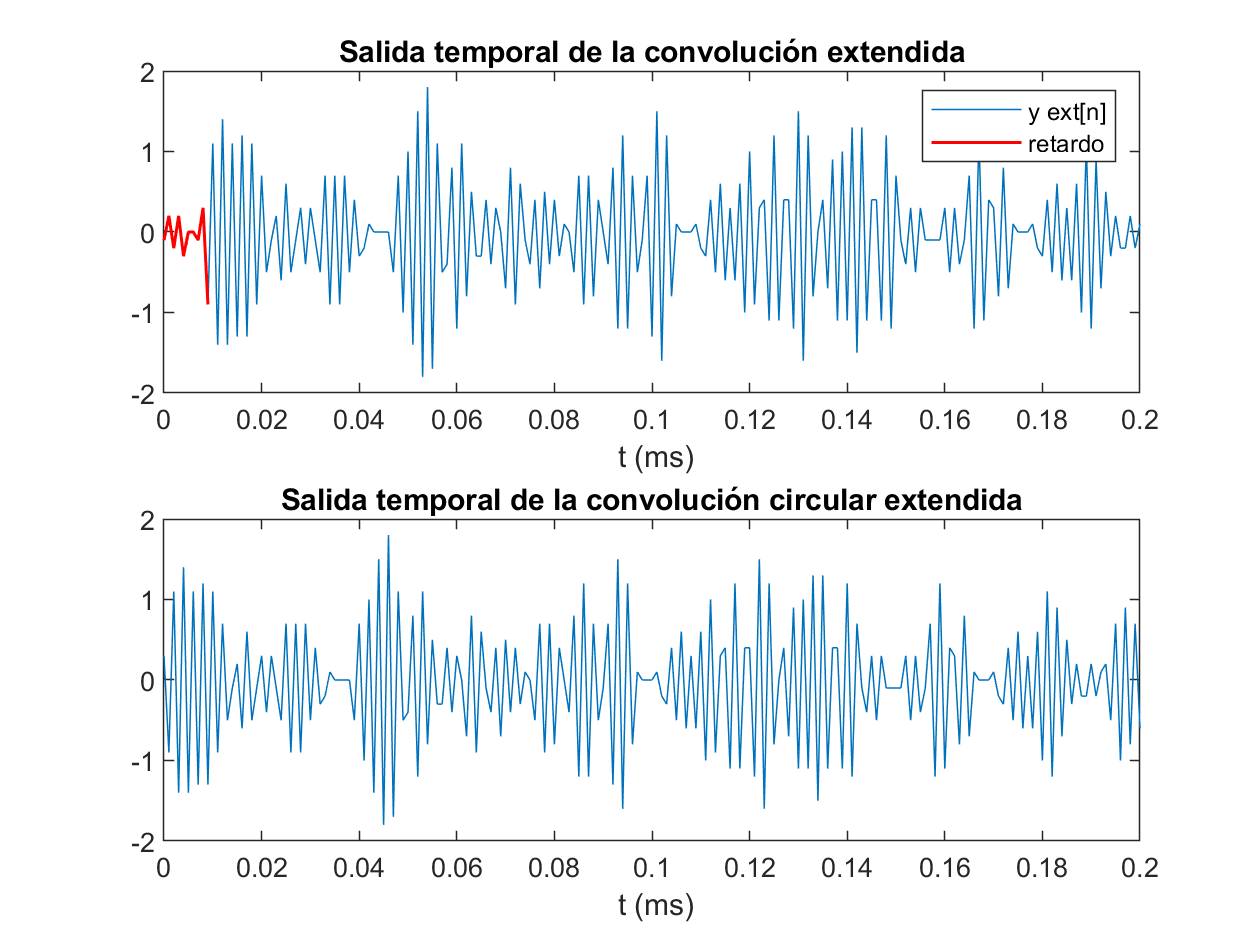

% Representacion diferencia y_ext e yc_ext
figure;
subplot(2,1,1);
grid minor;
plot(0:Ts:Ts*length(yext_n)-Ts, yext_n);
hold on;
retardo = yext_n(1:length(h_n)+1);
plot(0:Ts:Ts*length(retardo)-Ts, retardo,"r","LineWidth",1);
xlim([0, 0.2]);
xlabel(" t (s)");
title("Salida temporal de la convolución extendida");
legend("y ext[n]","retardo");
subplot(2,1,2);
plot(0:Ts:Ts*length(yc_ext_n)-Ts, yc_ext_n);
xlim([0, 0.2]);
xlabel(" t (s)");
title("Salida temporal de la convolución circular extendida");

En el primer subplot de la figura se ha resaltado en rojo la parte correspondiente al retardo producido por la convolución circular. Para observar mejor estas muestras, se ha restringido el intervalo temporal del inicio a 0.2 s. El número de muestras de este retardo se corresponde con la cantidad de muestras del prefijo cíclico, K. 

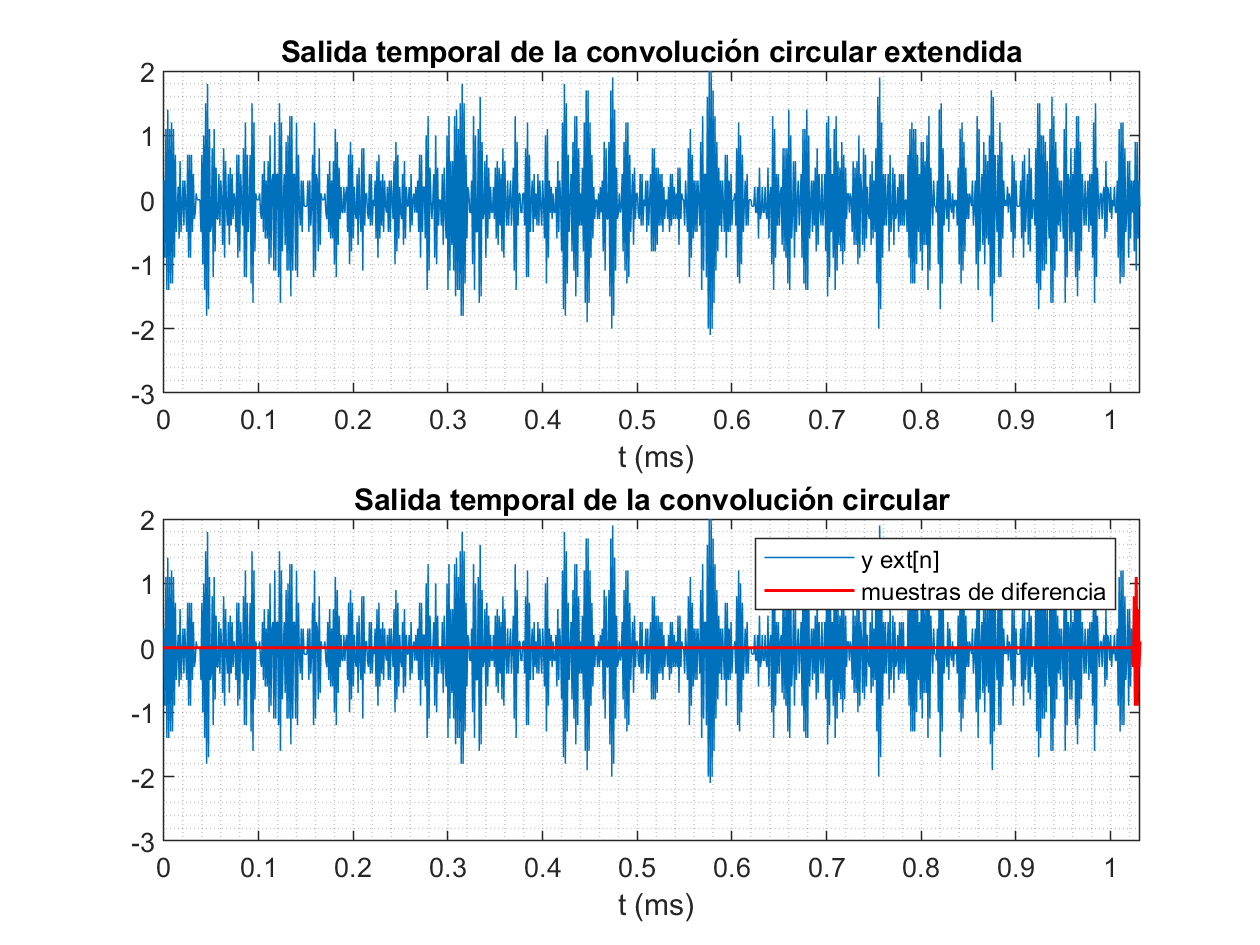

% Representacion diferencia yc[n] e yc_ext[n]
figure;
subplot(2,1,1);
plot(0:Ts:Ts*length(yc_ext_n)-Ts, yc_ext_n);
grid minor;
xlim([0, Ts*length(yc_ext_n)-Ts]);
xlabel(" t (s)");
title("Salida temporal de la convolución circular extendida");
subplot(2,1,2);
plot(0:Ts:Ts*length(yc_n)-Ts, yc_n);
hold on;
plot(0:Ts:Ts*length(yc_ext_n)-Ts,[yc_n zeros(1,K)]-yc_ext_n,"r","LineWidth",1);
grid minor;
xlim([0, Ts*length(yc_ext_n)-Ts]);
xlabel(" t (s)");
title("Salida temporal de la convolución circular");
legend("y ext[n]","muestras de diferencia");

En la figura anterior se marca la diferencia entre la convolución circular extendida y la no extendida, donde se puede apreciar como la discrepancia entre ambas señales es nula, excepto en las últimas muestras. Estas últimas K muestras se corresponden con la extensión. Por este motivo para extraer yc de yc_ext se precisa eliminar estas últimas muestras.

## 2.2.  Ecualización

clear all;

**1. Genere una señal OFDM del mismo modo que hizo en la práctica anterior, con las mismas 10 subportadoras moduladas en QPSK. Utilice el mismo valor de NFFT, pero en este caso limite el número de símbolos a 100 (Nofdm = 100). **

NFFT  =	128;  % Tamaño de la FFT
df    = 200;  % Separación entre portadoras (Hz)
Fs    =	NFFT*df;  % Frecuencia de muestreo (Hz)
Nf    =	10;  % Numero de portadoras con datos
m_ary =	4;  % Indicador de modulacion digital de cada portadora (QPSK)
SNR_vector = -5:1:15;  % Vector de relaciones SNR en el canal
 
% Generación de los bits a transmitir. Han de ser un multiplo entero de log2(m_ary)*Nf
Nofdm  =  100;  % Número de símbolos OFDM
txbits = round(rand(1,2*Nf*Nofdm));
 
% Generación de símbolos complejos resultantes de la modulación en QPSK. Se recomienda, aunque no es estrictamente necesario, que los símbolos se agrupen en una matriz de Nf filas y Nofdm columnas
mod = moduladorQPSK(txbits);
mod = reshape(mod,Nf,Nofdm);

% MODULACION OFDM
%  Incialización a cero
X = zeros(NFFT, Nofdm);

%  Asignación de los símbolos moduladores al espectro positivo
Nstart = 28+1;
Nend = 37+1;  
X(Nstart:Nend,:) = mod;

%  Asignación de los símbolos moduladores en orden inverso y conjugados al espectro negativo. Describa lo que realiza la función flipud.
X(NFFT/2+2:NFFT,:) = flipud(conj(X(2:NFFT/2,:)));

% Generación del vector de muestras temporales reales x como resultado de la modulación OFDM. Léase la documentación de las funciones IFFT y FFT de MATLAB
x = ifft(X,NFFT,"symmetric")*NFFT; % Señal transmitida, que tiene que ser real

Añada un intervalo de guarda de longitud l_cp = 16, relleno con ceros, a cada uno de los símbolos. A la señal OFDM con los 100 símbolos y sus intervalos de guarda correspondientes la llamaremos s[n].

% Se añade prefijo cíclico
l_cp = 16;
s.a = zeros(l_cp+NFFT,Nofdm);
s.a(l_cp+1:NFFT+l_cp,:) = x;

% Conversion a vector de una fila
s.a = reshape(s.a,1,[]);

**2. Simule que s[n] pasa por el canal h[n] del punto 2 del apartado anterior y calcule la señal recibida en el receptor (sin ruido). Para ello puede hacer uso del siguiente código:**

% Definicion del canal
h = [-0.1 0.3 -0.5 0.7 -0.9 0.7 -0.5 0.3 -0.1];

% Resultado del paso de s[n] por el canal h[n]
s_rx.a = conv(s.a, h);
s_rx.a = s_rx.a(1:end-length(h)+1);

**3. Elimine el intervalo de guarda de todos los símbolos recibidos. Puede resultar muy útil volver a organizar *****s_rx***** en forma matricial con *****Nofdm***** columnas y *****NFFT + l_cp *****filas:**

% Conversion a forma matricial
x_cp_rx.a = reshape(s_rx.a, NFFT+l_cp, Nofdm);

% Eliminar intervalos de guarda
x_rx.a = x_cp_rx.a(l_cp+1:NFFT+l_cp,:);

**4. Realice la ecualización en el dominio de la frecuencia de los símbolos recibidos con el canal ideal: **

% Implementación de la FFT para demodular la señal OFDM
X_RX.a = fft(x_rx.a,NFFT)/NFFT;

% Espectro de h[n]
H = fft(h,NFFT)/NFFT;

% dominio frecuencia
X_RX_EQ.a = X_RX.a ./ repmat(H.',1,Nofdm);

**5. Extraiga las subportadoras de datos de todos los símbolos ecualizados *****X_RX_EQ***** y compare con las subportadoras QPSK transmitidas, representando ambas constelaciones. Comente los resultados. **

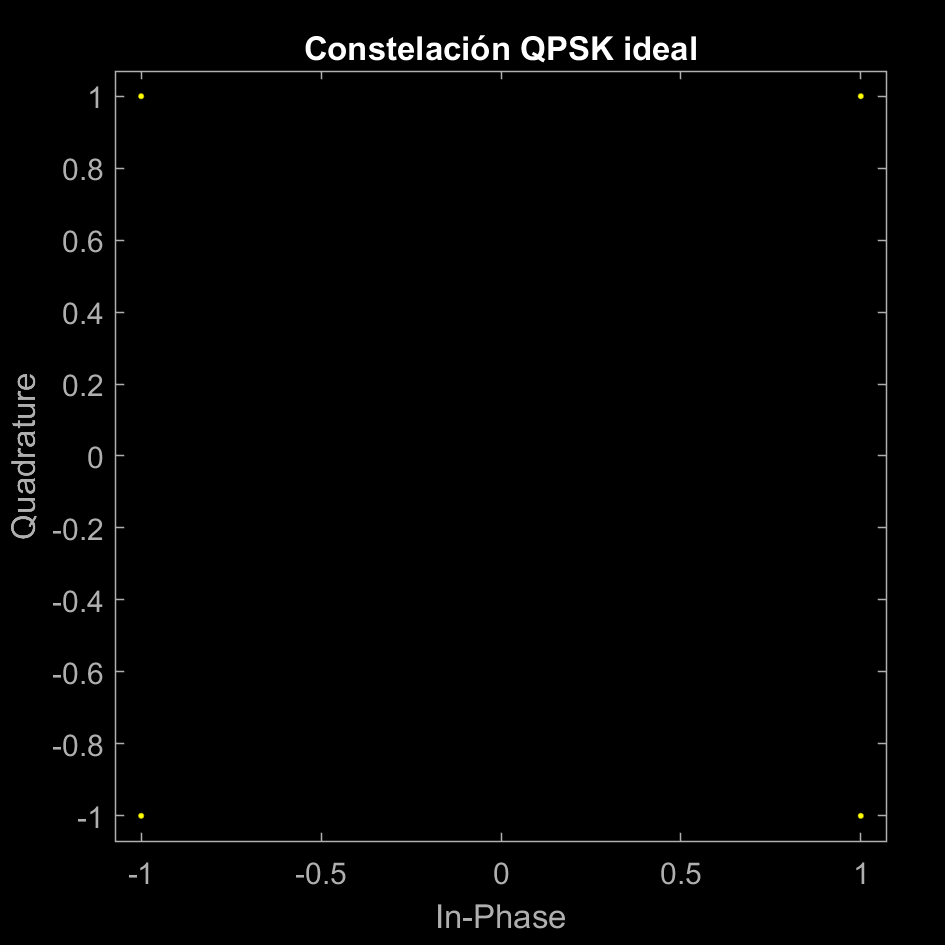

% Selección de la señal
X_RX_EQ.a = X_RX_EQ.a(Nstart:Nend,:);

% Representacion de las constelaciones
scatterplot(mod(1,:));
title("Constelación QPSK ideal");

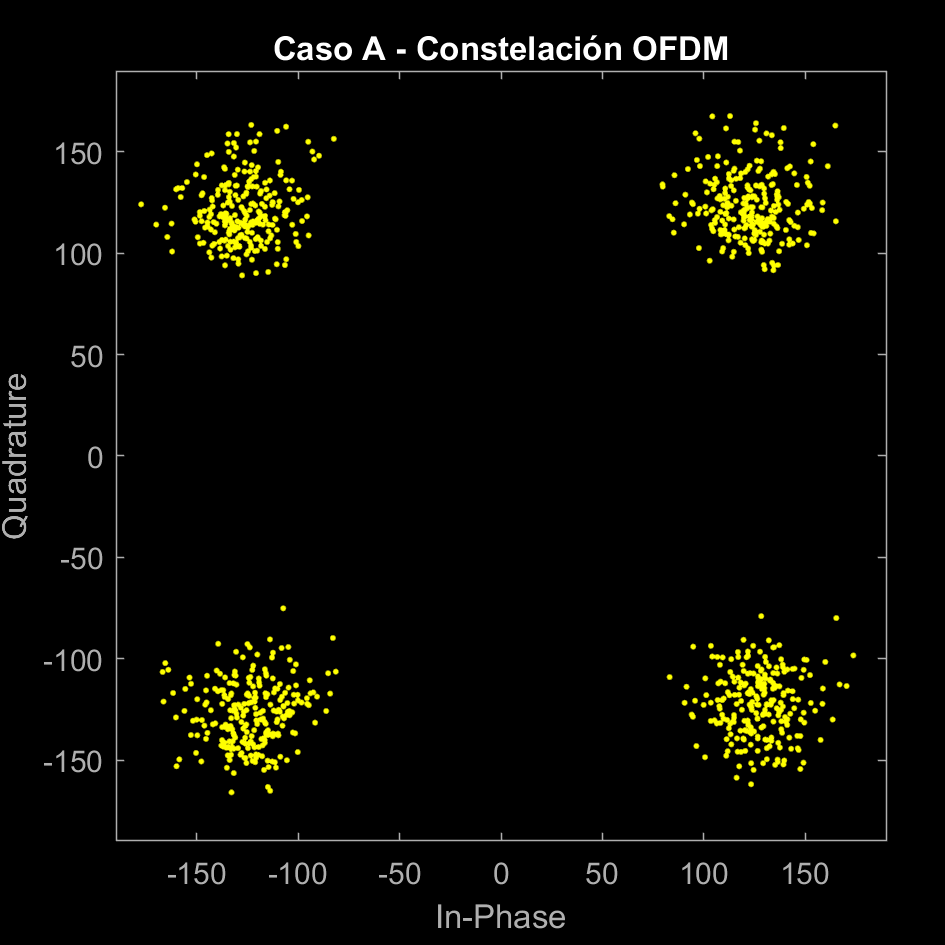

scatterplot(reshape(X_RX_EQ.a,1,[]));
title("Caso A - Constelación OFDM");

Para este primer caso A, se observa como hay una dispersión de los símbolos transmitidos, que contrastan con la constelación QPSK ideal. Como el prefijo cíclico está compuesto en este caso únicamente por ceros, no aporta ventaja y añade el ruido que provoca la dispersión de los símbolos.

**6. Repita los puntos 1-5 para el caso b). Para ello incluya una extensión cíclica de longitud l_cp = 4 como intervalo de guarda. **

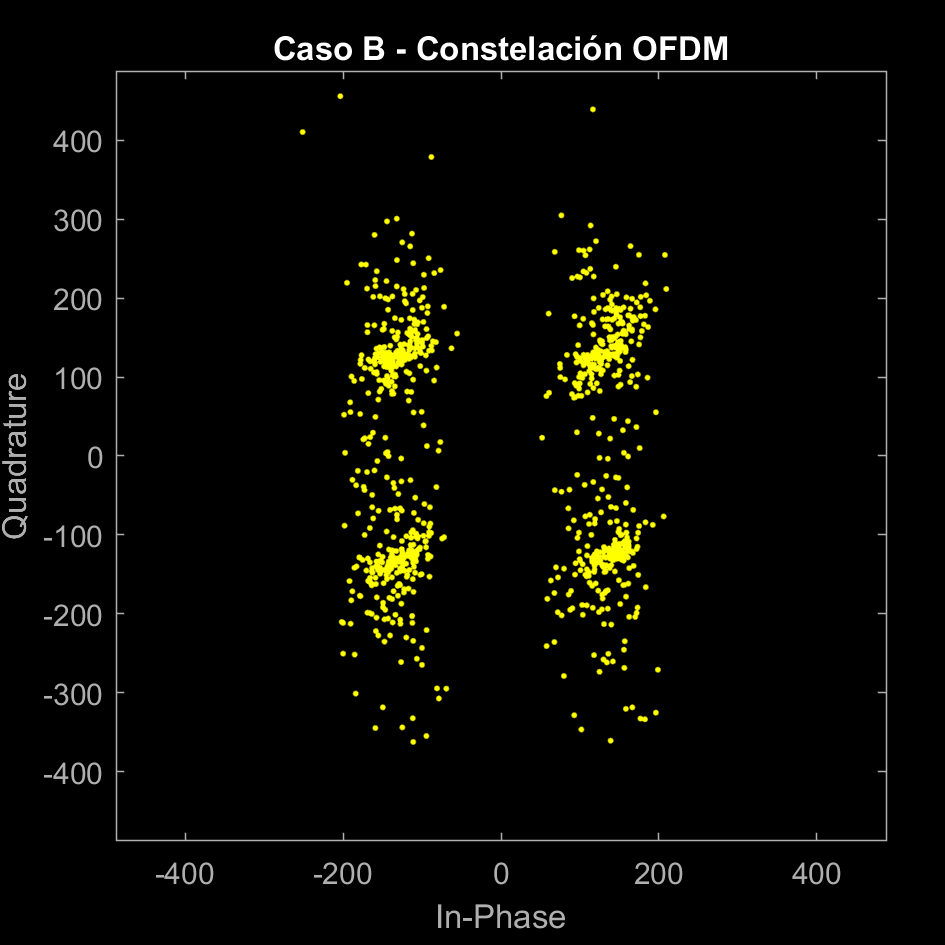

% Se añade prefijo cíclico
l_cp = 4;
s.b = zeros(l_cp+NFFT,Nofdm);
s.b(1:l_cp,:) = x(end-l_cp+1:end,:);
s.b(l_cp+1:NFFT+l_cp,:) = x;

% Conversion a vector de una fila
s.b = reshape(s.b,1,[]);

% Resultado del paso de s[n] por el canal h[n]
s_rx.b = conv(s.b, h);
s_rx.b = s_rx.b(1:end-length(h)+1);

% Conversion a forma matricial
x_cp_rx.b = reshape(s_rx.b, NFFT+l_cp, Nofdm);

% Eliminar intervalos de guarda
x_rx.b = x_cp_rx.b(l_cp+1:NFFT+l_cp,:);

% Implementación de la FFT para demodular la señal OFDM
X_RX.b = fft(x_rx.b,NFFT)/NFFT;

% dominio frecuencia
X_RX_EQ.b = X_RX.b ./ repmat(H.',1,Nofdm);

% Selección de la señal
X_RX_EQ.b= X_RX_EQ.b(Nstart:Nend,:);

% Representacion de las constelaciones
scatterplot(reshape(X_RX_EQ.b,1,[]));
title("Caso B - Constelación OFDM");

En segundo caso B, donde se utiliza un prefijo cíclico de 4 muestras se aprecia como, en la contelación de símbolos, estos se mezlan y entrelazan, dando como resultado un panorama confuso. Estos se debe a que pese a introducir las últimas muestras de la señal (al contrario que antes), el número de estas es inferior al óptimo, que lo marca la longitud del filtro h[n] menos una muestra. Por este motivo, aparece esa dispersión de los símbolos, y aumenta la BER. 

**8. Repita los puntos 1-5 para el caso c). Para ello incluya una extensión cíclica de longitud l_cp = 16 como intervalo de guarda.**

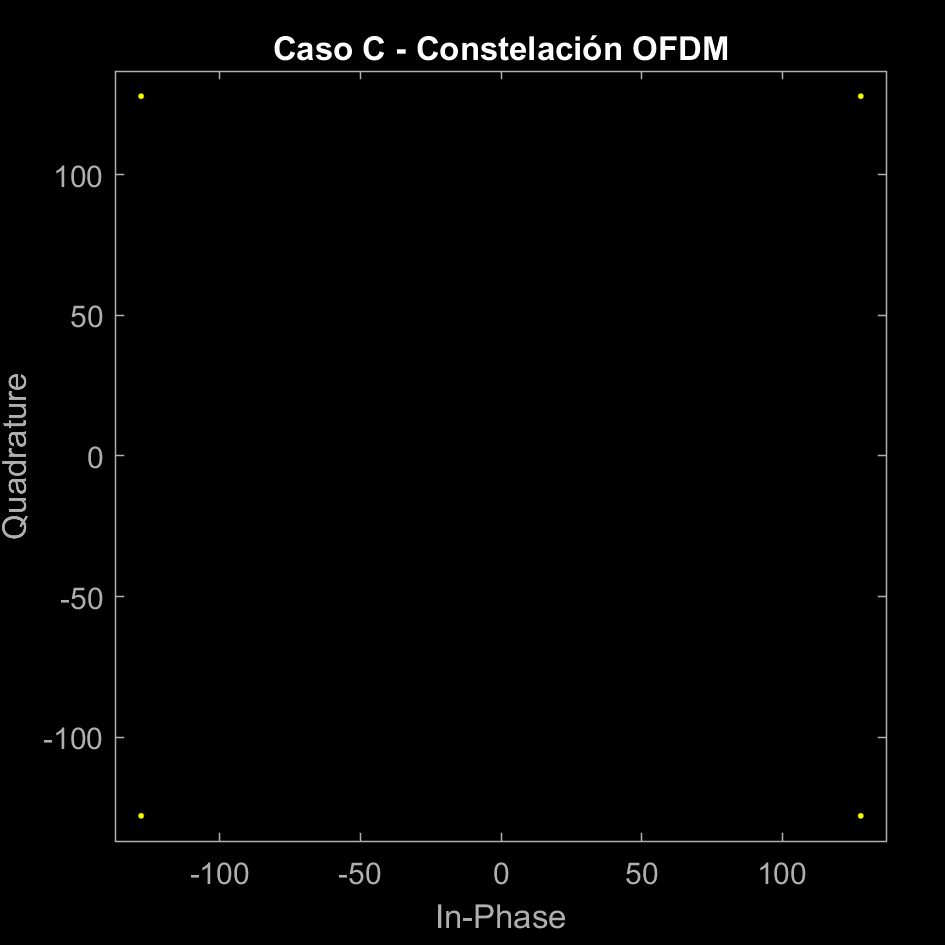

% Se añade prefijo cíclico
l_cp = 16;
s.c = zeros(l_cp+NFFT,Nofdm);
s.c(1:l_cp,:) = x(end-l_cp+1:end,:);
s.c(l_cp+1:NFFT+l_cp,:) = x;

% Conversion a vector de una fila
s.c = reshape(s.c,1,[]);

% Resultado del paso de s[n] por el canal h[n]
s_rx.c = conv(s.c, h);
s_rx.c = s_rx.c(1:end-length(h)+1);

% Conversion a forma matricial
x_cp_rx.c = reshape(s_rx.c, NFFT+l_cp, Nofdm);

% Eliminar intervalos de guarda
x_rx.c = x_cp_rx.c(l_cp+1:NFFT+l_cp,:);

% Implementación de la FFT para demodular la señal OFDM
X_RX.c = fft(x_rx.c,NFFT)/NFFT;

% dominio frecuencia
X_RX_EQ.c = X_RX.c ./ repmat(H.',1,Nofdm);

% Selección de la señal
X_RX_EQ.c= X_RX_EQ.c(Nstart:Nend,:);

% Representacion de las constelaciones
scatterplot(reshape(X_RX_EQ.c,1,[]));
title("Caso C - Constelación OFDM");

En este último caso C, como el prefijo cíclico es de 16 muestras (más de las sufientes (8)) el resultado se muestra sin la dispersión que sí tenían los casos anteriores. La probabilidad de error debida a la modulación OFDM bajo estas condiciones es prácticamente nula. 